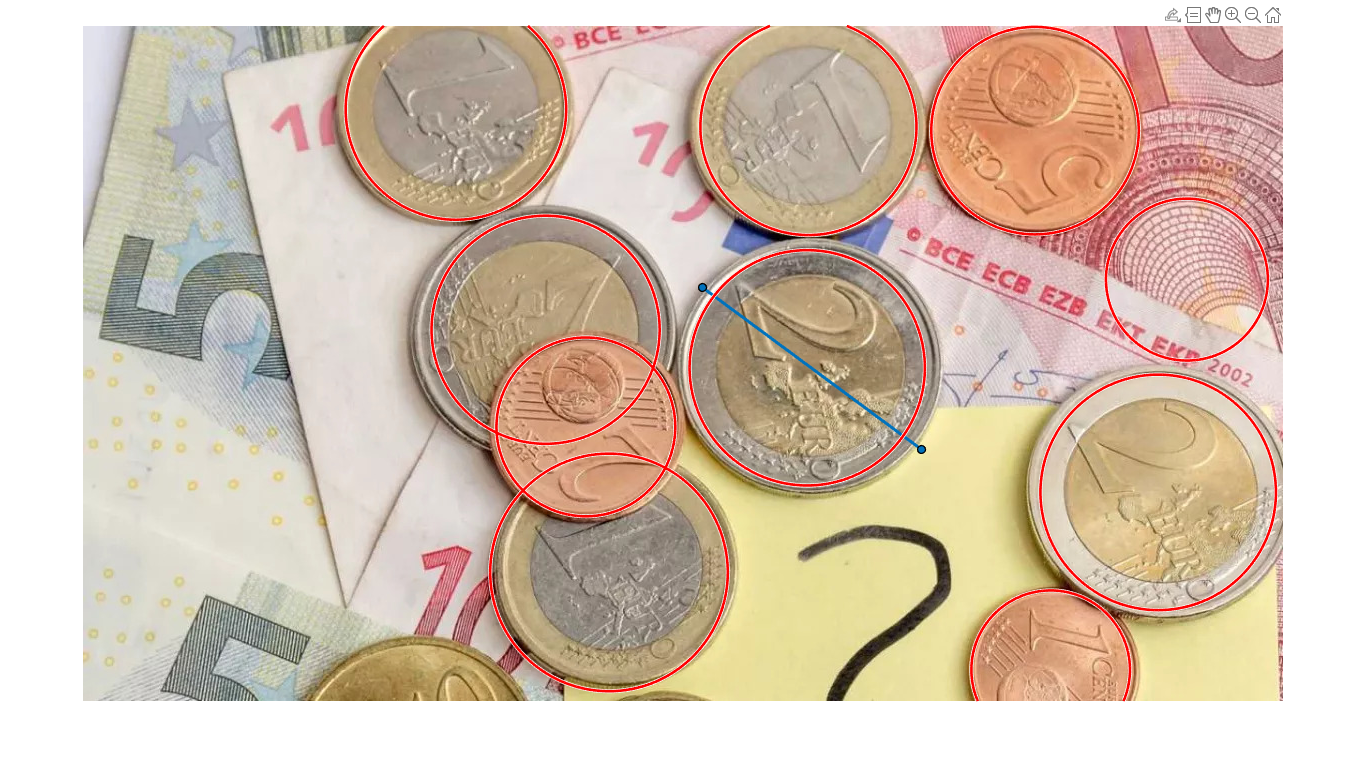

radiusPadding = 10;
cut(radiusPadding);

function y = cut(radiusPadding)
    IOrig = imread("muenzenVerdeckung.jpg");
    imshow(IOrig);
    
    d = drawline;
    pos = d.Position;
    diffPos = diff(pos);
    diameter = round(hypot(diffPos(1), diffPos(2)));
    
    [centers, radii] = imfindcircles(IOrig, [round(diameter * 0.25), diameter], ...
        "EdgeThreshold", 0.25, "Sensitivity", 0.97);
    viscircles(centers, radii);
    
    coinCount = size(centers, 1);
    
    coins = {1, coinCount};

    imagesize = size(IOrig);
    
    for i = 1:coinCount
        x = round(centers(i, 1));
        y = round(centers(i, 2));
        r = round(radii(i)) + radiusPadding;

        [xx, yy ] = ndgrid((1:imagesize(1))-y,(1:imagesize(2))-x);

        mask = uint8((xx.^2 + yy.^2)<((r+radiusPadding)^2));
        IMasked = uint8(zeros(imagesize));
        IMasked(:,:,:) = IOrig(:,:,:).*mask;

        coins{i} = imcrop(IOrig, [x - r, y - r, 2 * r + 40, 2* r + 40]);
        coins{i} = IMasked;
        coins{i} = imcrop(IMasked, [x - r, y - r, 2 * r , 2* r ]);
    
        str = sprintf("readCoins/img_%02d.jpg",i);
        imwrite(coins{i}, str);
    
    end
    y = coins;
end